# Sistemas de Visión Artificial

# **Práctica 1. Parte 2. Ejemplo de detector de movimiento**

**Autor(es): Alejandro Fernandez Ambros, Cristina Martinez Toledo**

**Fecha: 28/09/2026**

Analice el código del siguiente detector de movimiento e incluya alguna de las modificaciones realizada sobre la captura en el imageAcquisitionExplorer (cambio de tamaño de la imagen, definición de ROI, brillo, contraste, etc.).

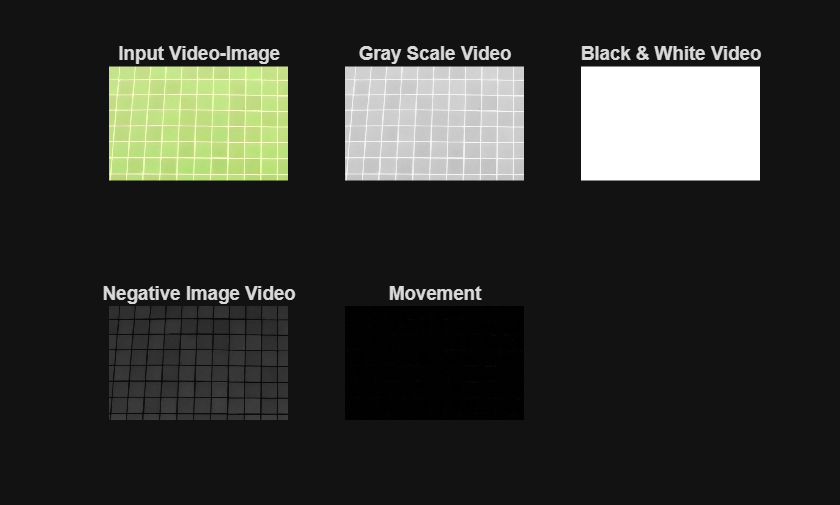


clear all
close all


% limpiar todo texto y output 
clc 

% Inicializa el objeto de entrada de video. 
% - Winvideo: Indica el adaptador de captura nativo de Windows 
% - 1: Especifica el ID del dispositivo conectado
vid = videoinput('winvideo', 1); 

% Configura la captura para que ocurra de forma indefinida
set(vid,'TriggerRepeat',Inf);

% Define el intervalo de captura de fotogramas 
% (captura el fotograma 5, el 10, 15, ...)
vid.FrameGrabInterval = 5;


%*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*
vid.ReturnedColorspace = "rgb";
vid.ROIPosition = [81 22 488 311];

% Obtener el objeto que controla los parámetros físicos de la cámara
src = getselectedsource(vid);

src.Brightness = -37;
src.Contrast = 56;
src.Gamma = 181;
src.Hue = 40;
src.Saturation = 84;
src.Sharpness = 1;
src.WhiteBalance = 4563;
src.WhiteBalanceMode = "manual";
%*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*


% Info de cada propiedad de la cámara:
propinfo(src,'Brightness')
propinfo(src,'Contrast')
propinfo(src,'Gamma')
propinfo(src,'Hue')
propinfo(src,'Saturation')
propinfo(src,'Sharpness')
propinfo(src,'WhiteBalance')
% Pone que todos los parámetros son "Read only while running", así que no se pueden modificar durante la grabación, solo antes


start(vid);

try
    while(vid.FramesAcquired<=110) % Stop after 110 frames
        % Extrae exactamente 2 fotogramas de la memoria intermedia (buffer) de la cámara y los guarda en la matriz IM. 
        % Al pedir 2 fotogramas a la vez, IM se convierte en una matriz de 4 dimensiones: [Alto, Ancho, Canales de Color (RGB), Número de Fotograma]
        IM = getdata(vid,2);

        IMGray = rgb2gray(IM(:,:,1:3));
        IMbw=im2bw(IMGray,0.5);
        IMneg=imadjust(IMGray,[0 1],[1 0]);
        subplot(2,3,1);imshow(IM(:,:,:,1));title('Input Video-Image')
        subplot(2,3,2);imshow(IMGray);title('Gray Scale Video')
        subplot(2,3,3);imshow(IMbw);title('Black & White Video')
        subplot(2,3,4);imshow(IMneg);title('Negative Image Video')

        % Separa el fotograma 1 del 2
        i1=IM(:,:,:,1);
        i2=IM(:,:,:,2);
        
        i1=rgb2gray(i1(:,:,1:3));
        i2=rgb2gray(i2(:,:,1:3));

        % Convierte los datos a tipo double para poder hacer operaciones matemáticas precisas
        % Resta los dos fotogramas:
        % - Si nada se ha movido, la resta dará 0 (negro). 
        % - Si un objeto cambió de posición entre el fotograma 1 y el 2, la resta dejará un "rastro" o silueta brillante.

        % - Abs asegura que la diferencia sea siempre positiva. 
        % - El / 256 normaliza el resultado para que se pueda mostrar bien:
        %   imshow si le das uint8, espera valores entre 0 y 255, pero si le das double, espera valores entre 0.0 y 1.0

        m=abs(double(i1)-double(i2))/256;
        subplot(2,3,5);imshow(m);title('Movement')
    end
    % Apaga el motor de captura de la cámara
    stop(vid);
    
catch ME
    stop(vid);
    disp(ME.message)
end

La **entrega correspondiente a la parte 2 de la práctica 1 **será este mlx modificado para incluir la modificación varios parámetros de la captura (ROI, brillo, etc...), incluyendo en la parte superior, en el espacio reservado para ello, el nombre de los autores y la fecha.